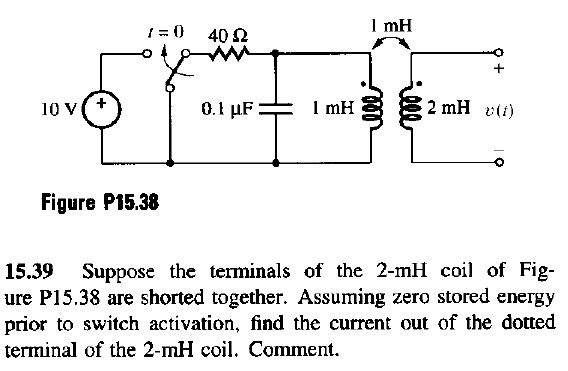

clc, clear, close all
format short g

vf = 10;
c = 0.1e-6;
l1 = 1e-3;
l2 = 2e-3;
lm = 1e-3;


realizamos un analisis de mallas, podemos ver que tenemos trs mallas al cerrar el interruptor.

syms i1 i2 i3 z1 z2 z3 z4 z5

% z1 = 40;
% z2 = 1/(j*w*c);
% z3 = j*w*l1;
% z4 = j*w*l2;
% z5 = j*w*lm;

ec1= simplify(-10+40*i1+z2*i1==0) 

$$ec1 = i_{1}\,\left(z_{2}+40\right)=10$$

ec2= simplify(z2*i2+z3*i2-z5*i3==0)

$$ec2 = i_{2}\,\left(z_{2}+z_{3}\right)=i_{3}\,z_{5}$$

ec3 = simplify(z4*i3-z5*i2==0)

$$ec3 = i_{2}\,z_{5}=i_{3}\,z_{4}$$

m = [17 -12 0;6 -26 5;0 1 -4];
n = [180;0;18];
h = m\n

h =     12
     2
    -4


y asi obtenemos las correintes en cada malla